# Cosine forcing

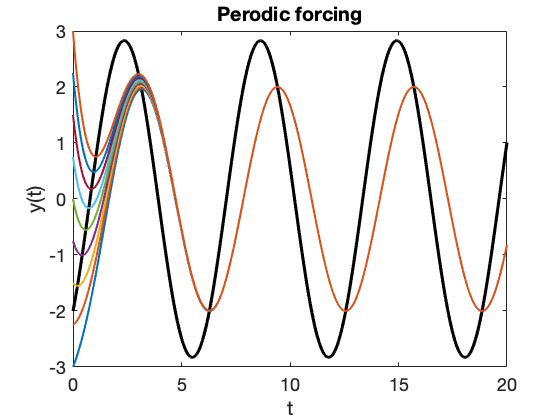


q = @(t) 2*sin(t)-2*cos(t);
dydt = @(t,y) -y + q(t);
t = linspace(0,20,1000);
clf
plot(t,q(t),'k','linew',3)
hold on
for y0 = -3:.75:3
    [t,y] = ode45(dydt,t,y0);
    plot(t,y)
end
xlabel('t'), ylabel('y(t)')
title('Perodic forcing')